x = readmatrix('parameter_estimation2.csv' );

phi = x(:,2);

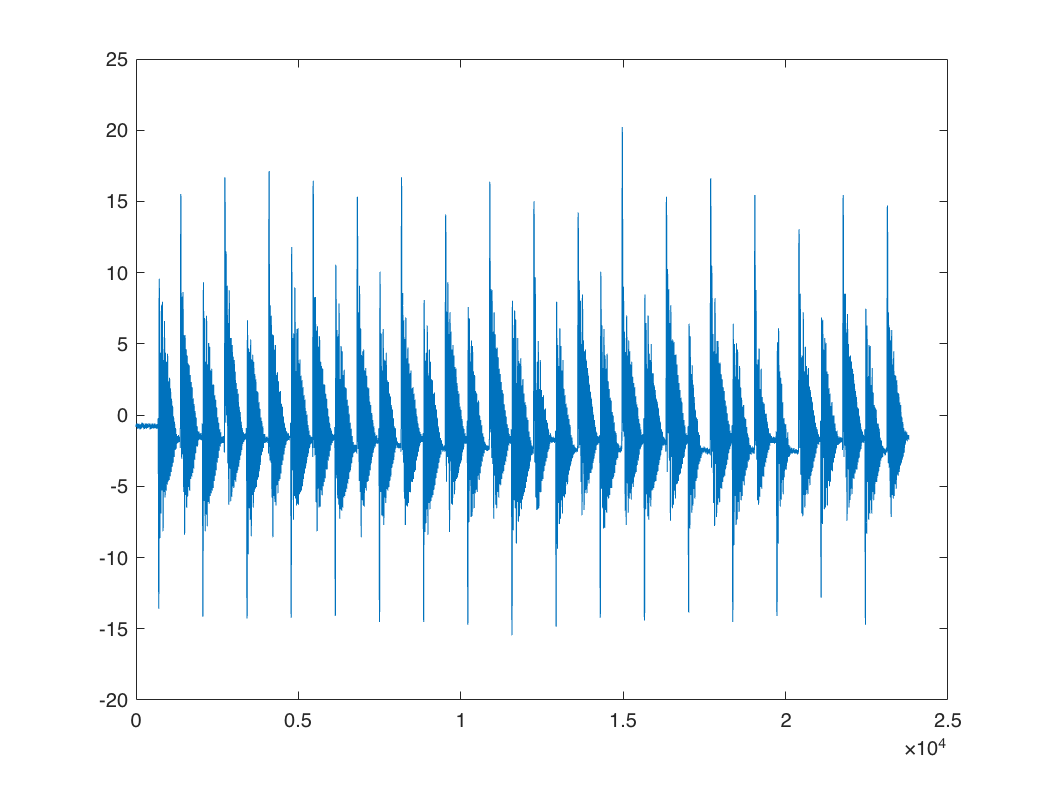

plot (phi)

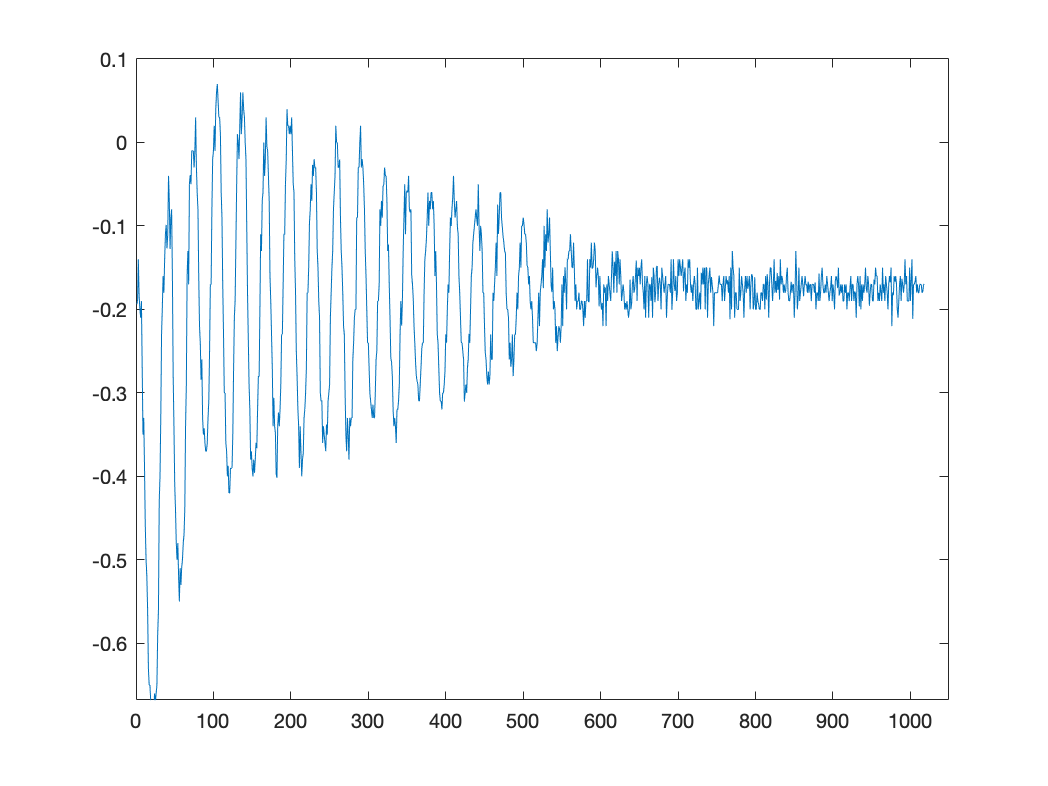

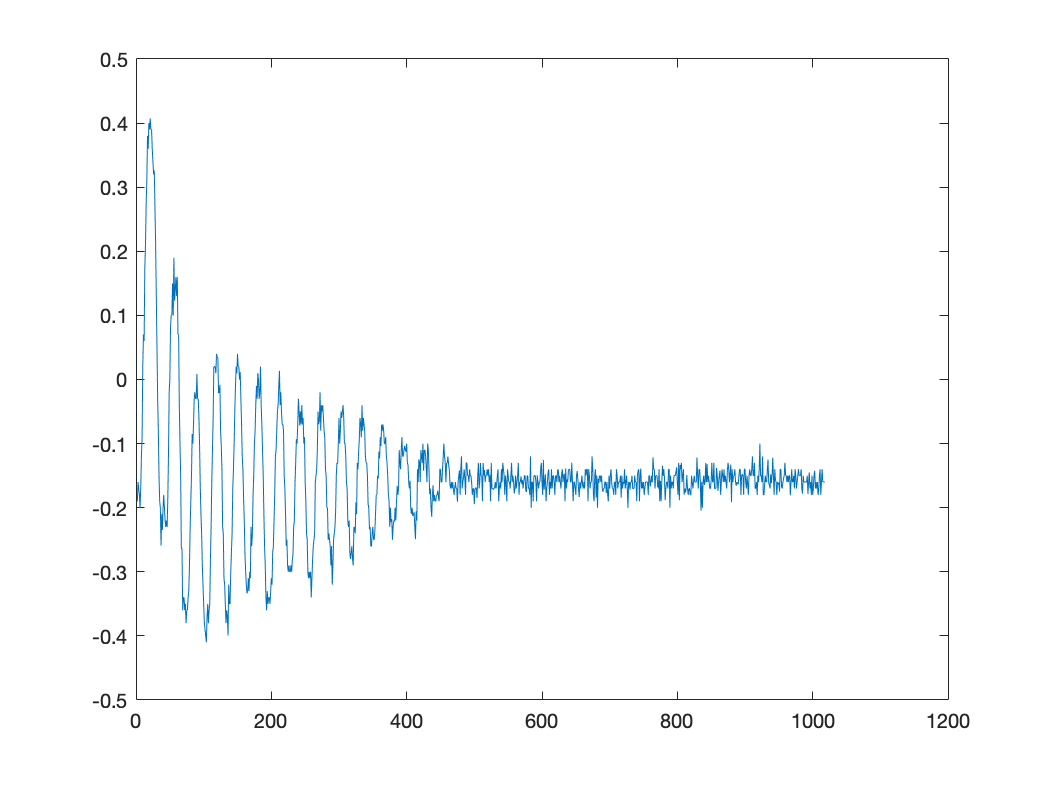

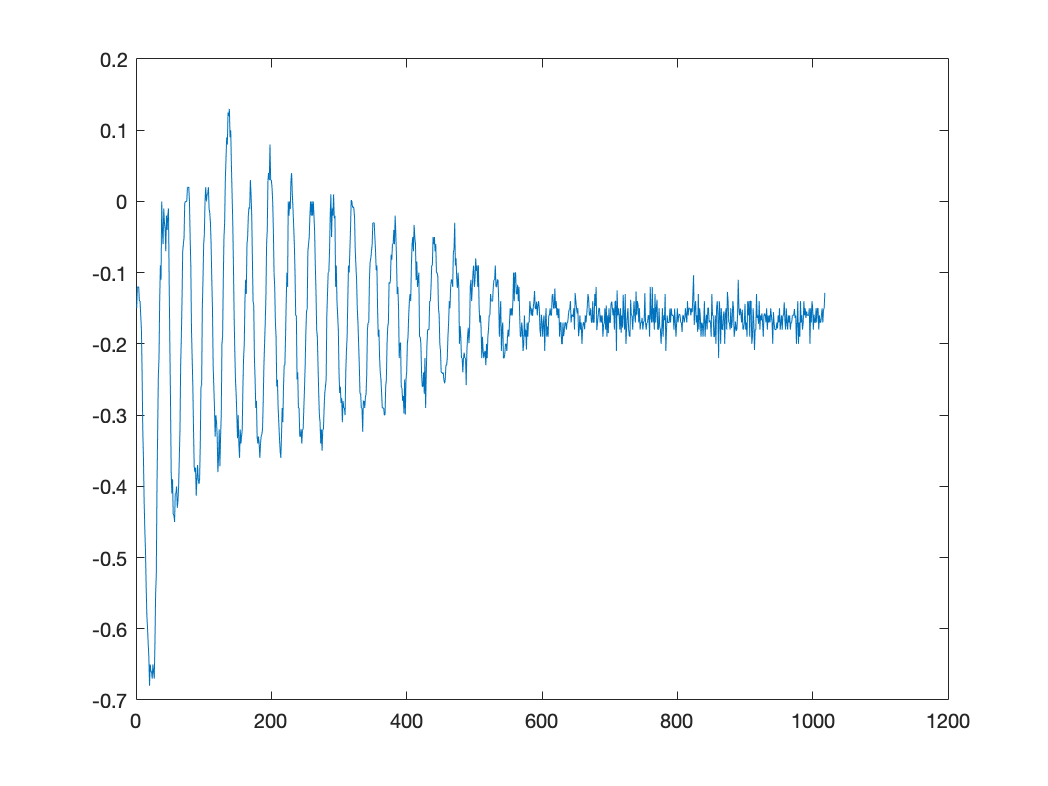

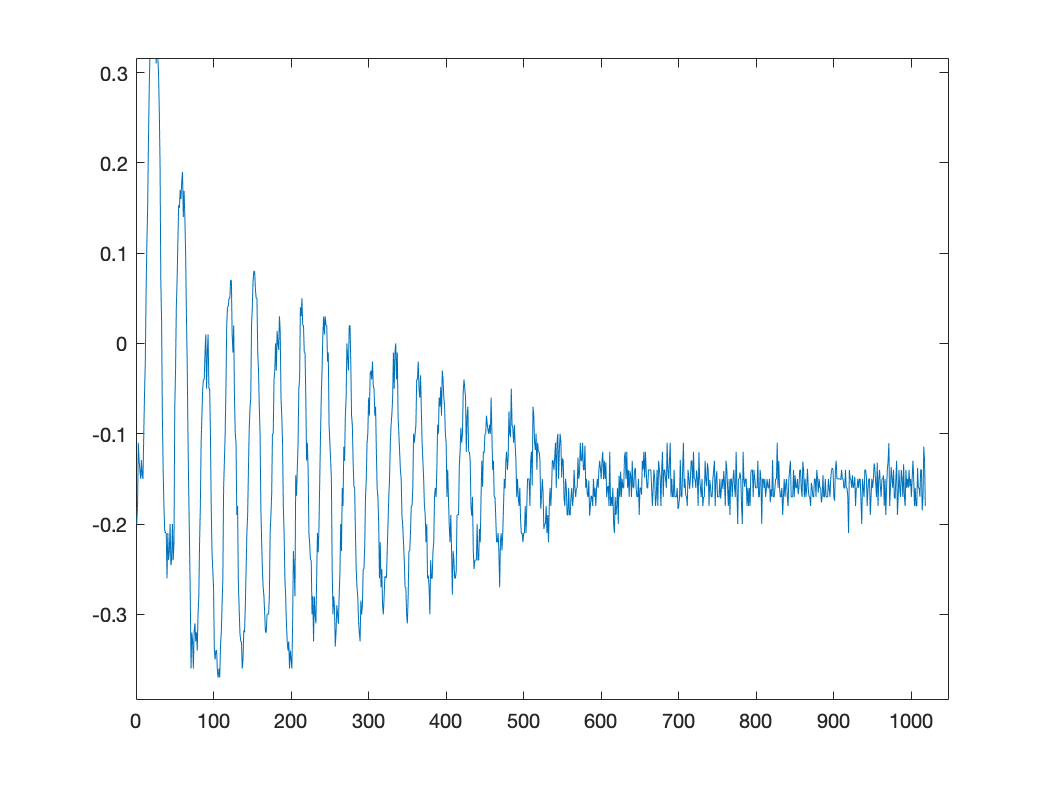

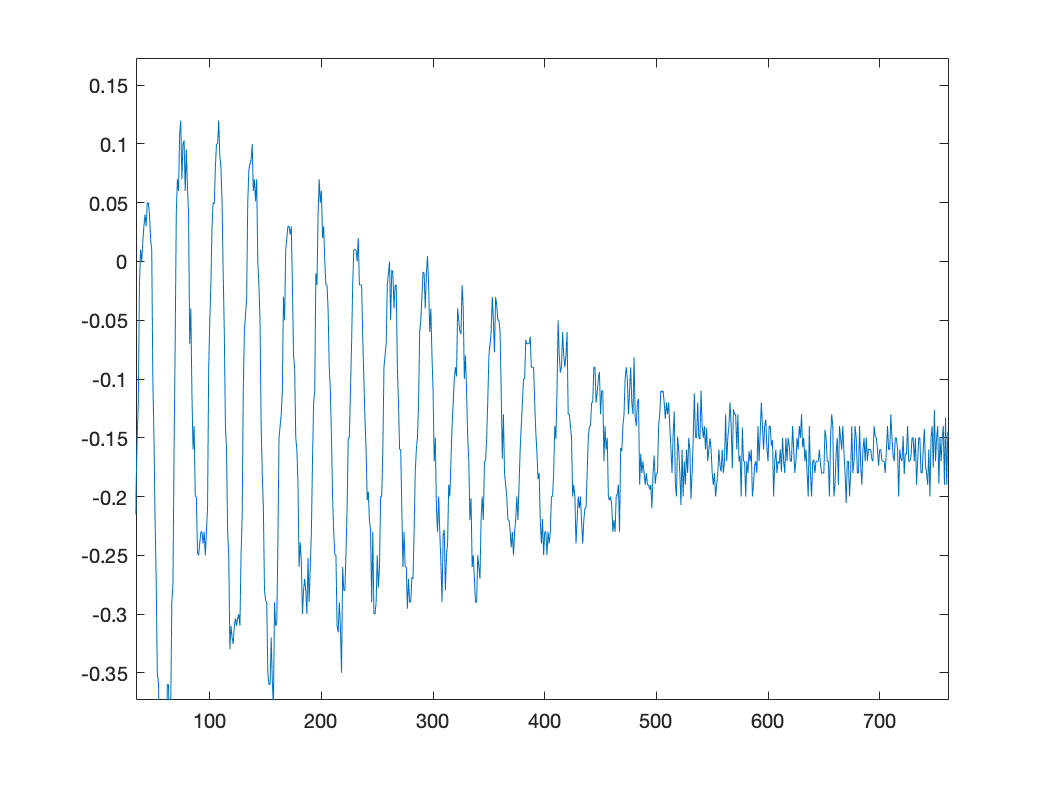

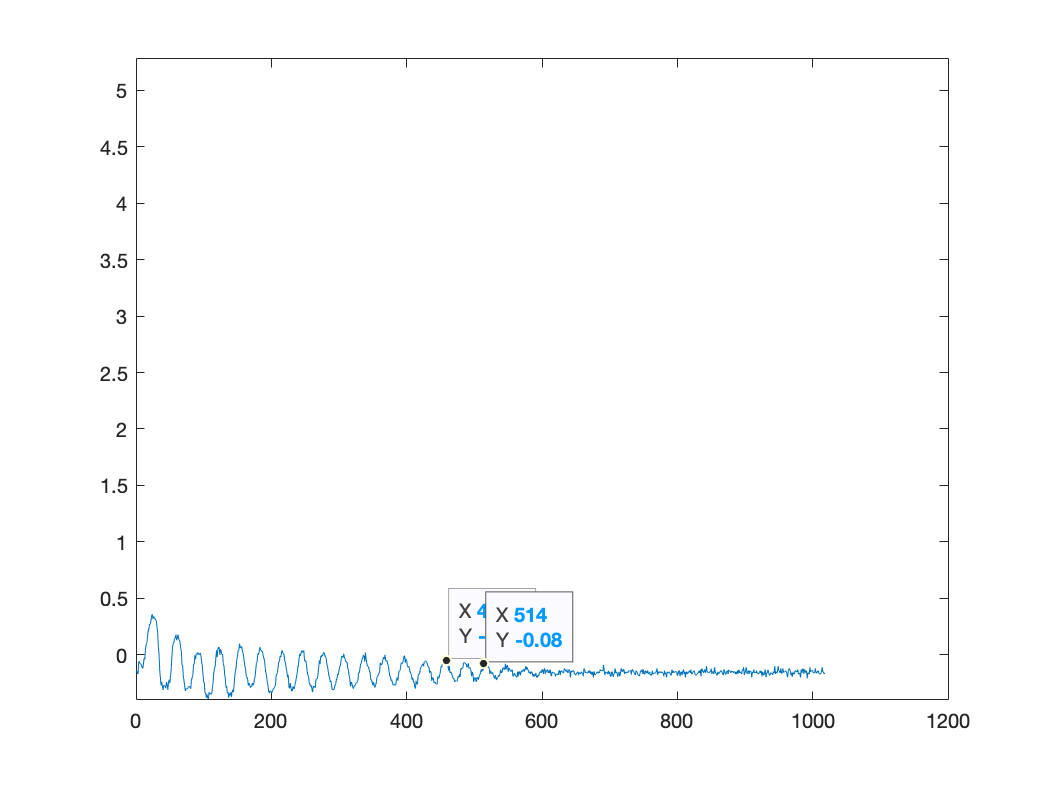

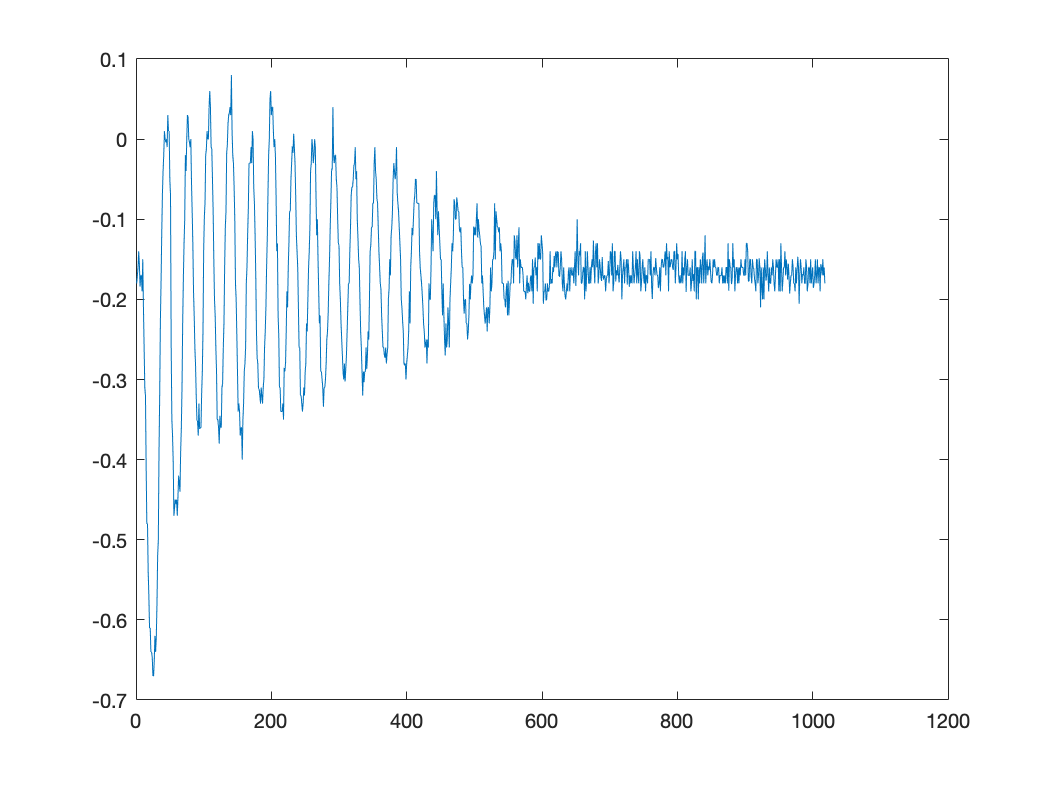

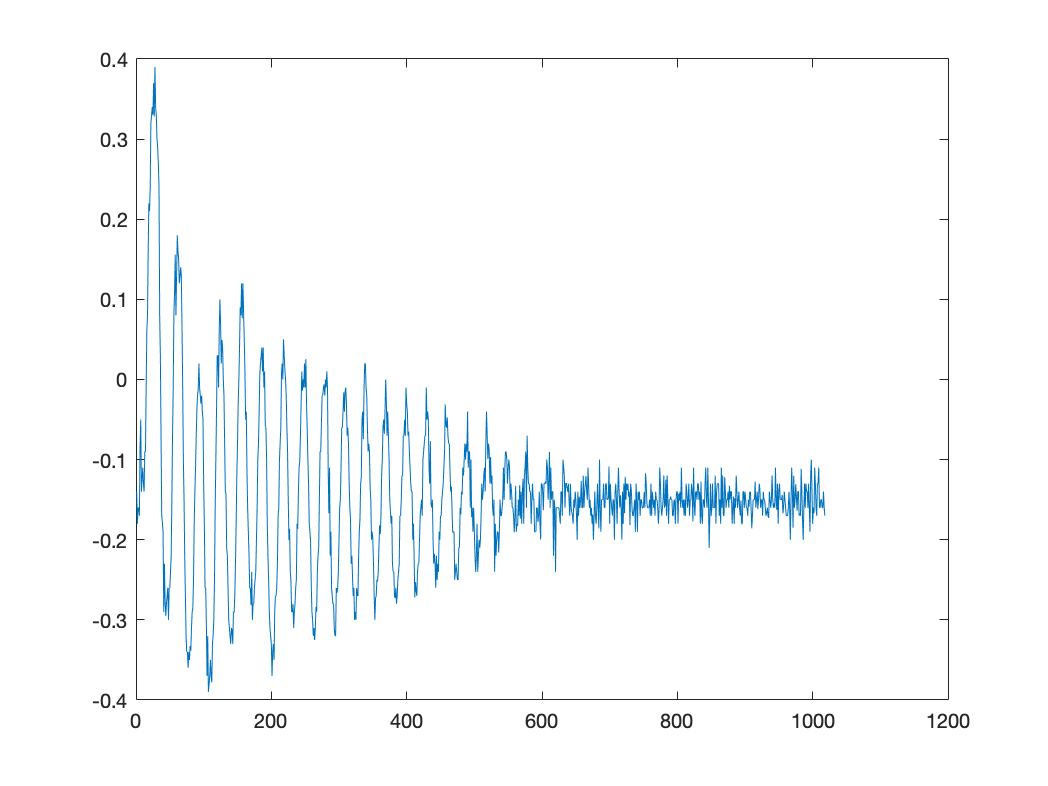

for j = 1:16
    plot (phi((1018*(j-1))+1:1018*j));
    figure;
end

maxX = zeros(16,1);
L = 1018; %No. eo elements in one window 
Fs = 85; % sampling frequency
for i = 1:16
   y = fft(phi((1018*(i-1))+1:1018*i));
   P2 = abs(y/L);
   P1 = P2(1:L/2+1);
   P1(1) = 0; % make dc component zero 
   P1(2:end-1) = 2*P1(2:end-1);
   f = Fs*(0:(L/2))/L;
   plot(f,P1) 
   hold on;
   title('Single-Sided Amplitude Spectrum of X(t)')
   xlabel('f (Hz)')
   ylabel('|P1(f)|')
   maxF = max(P1);  % Find max value over all elements.
   indexOfFirstMax = find(P1 == maxF, 1, 'first');  % Get first element that is the max.
   % Get the x value(frequency) at that index
   maxX(i) = f(indexOfFirstMax);
end

Unrecognized function or variable 'phi'.

   hold off
plot(maxX)

wd = sum(maxX)/16;
wd  %damped frequency 

wd = 2.7397

coeff_of_damping = 0.000279

coeff_of_damping = 2.7900e-04

wn = 17.2688

wn = 17.2688

l = 0.0328

l = 0.0328

%2,4,8 ,13,16,22,24,26,32 v1
% 1,4,5,6,11 v2

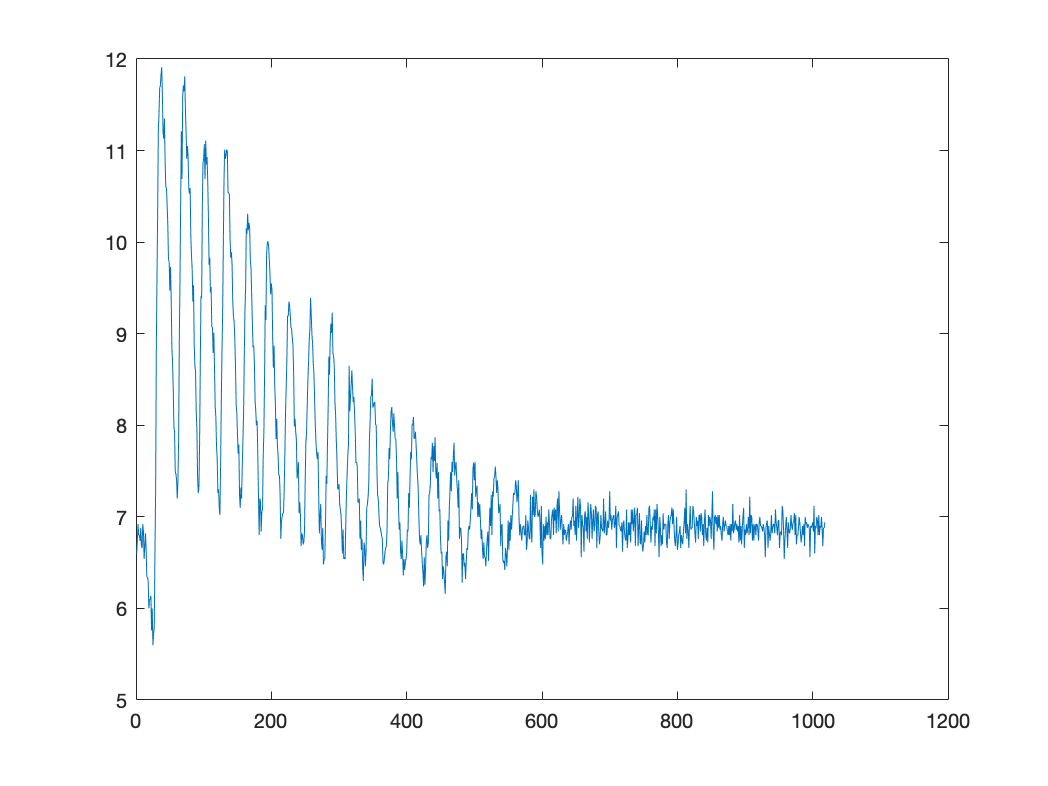

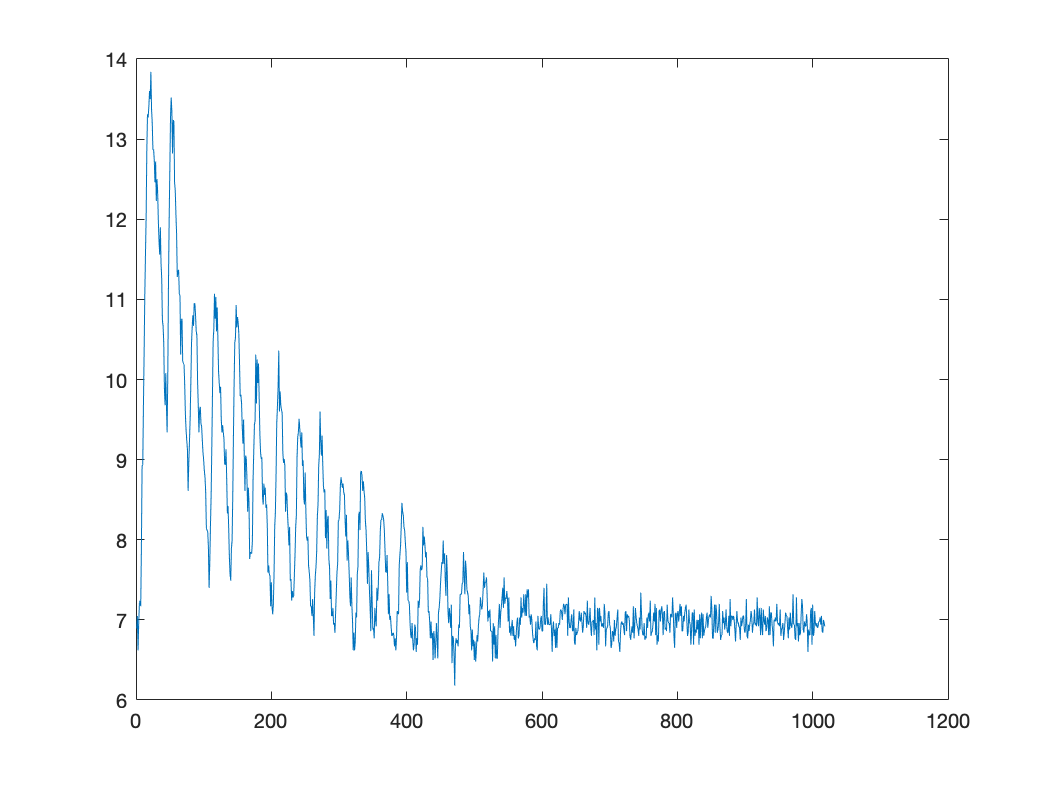

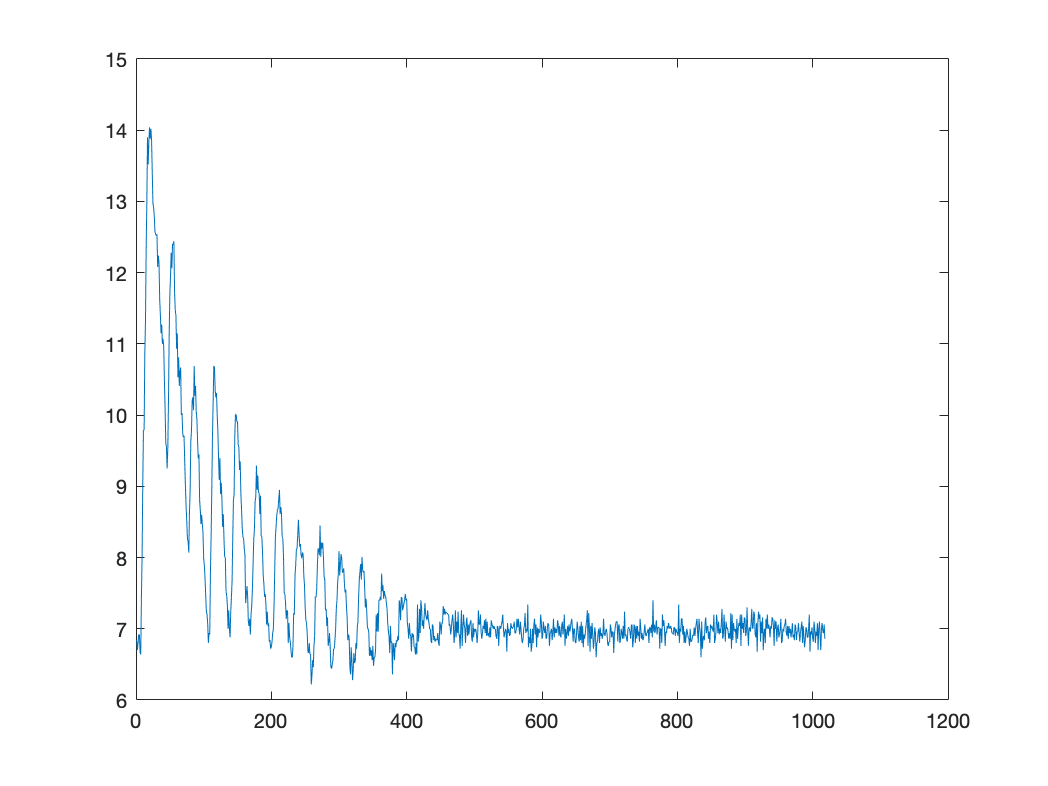

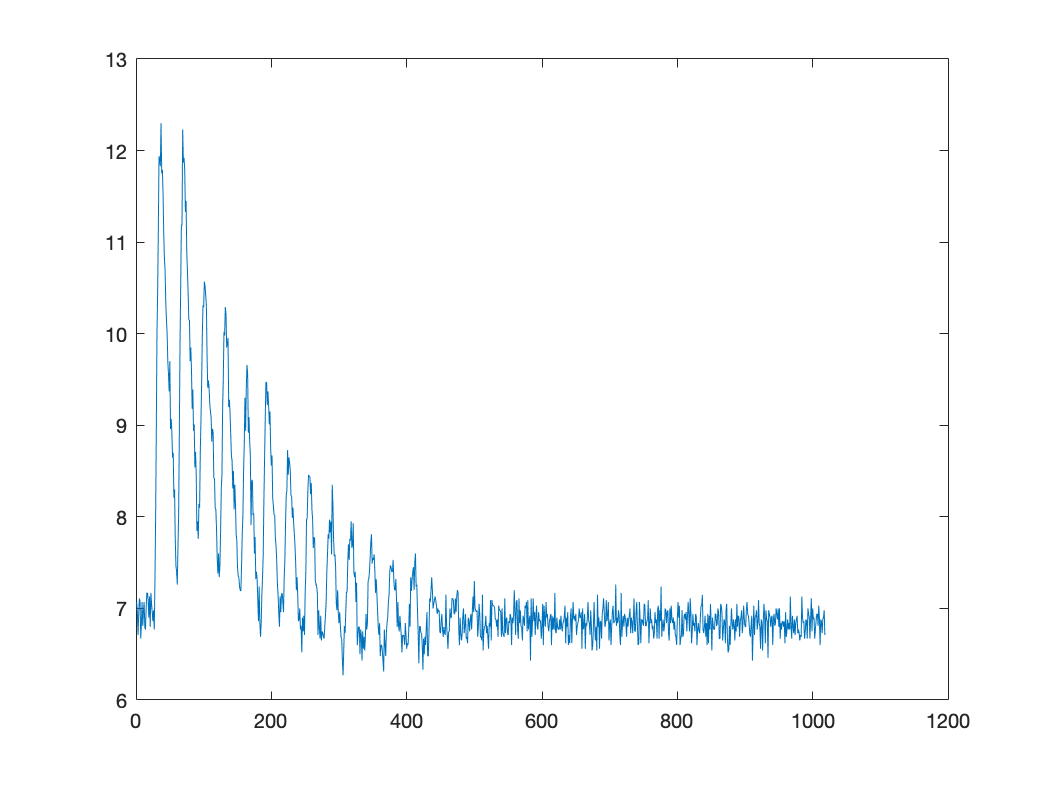

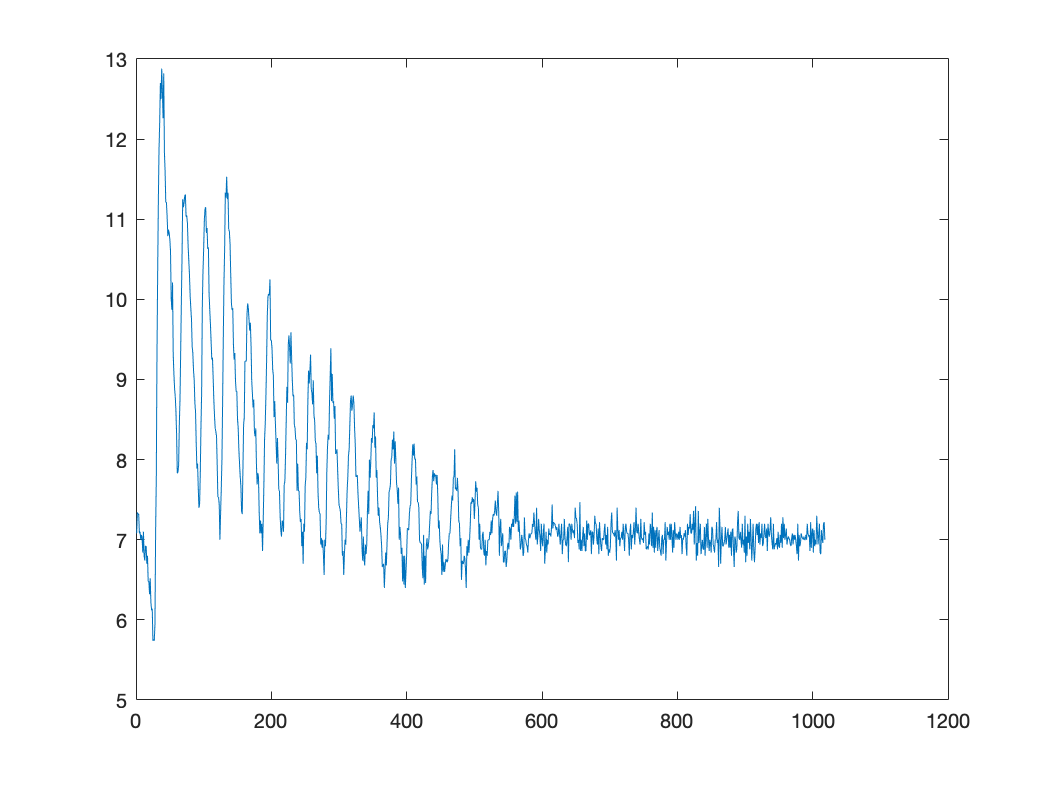

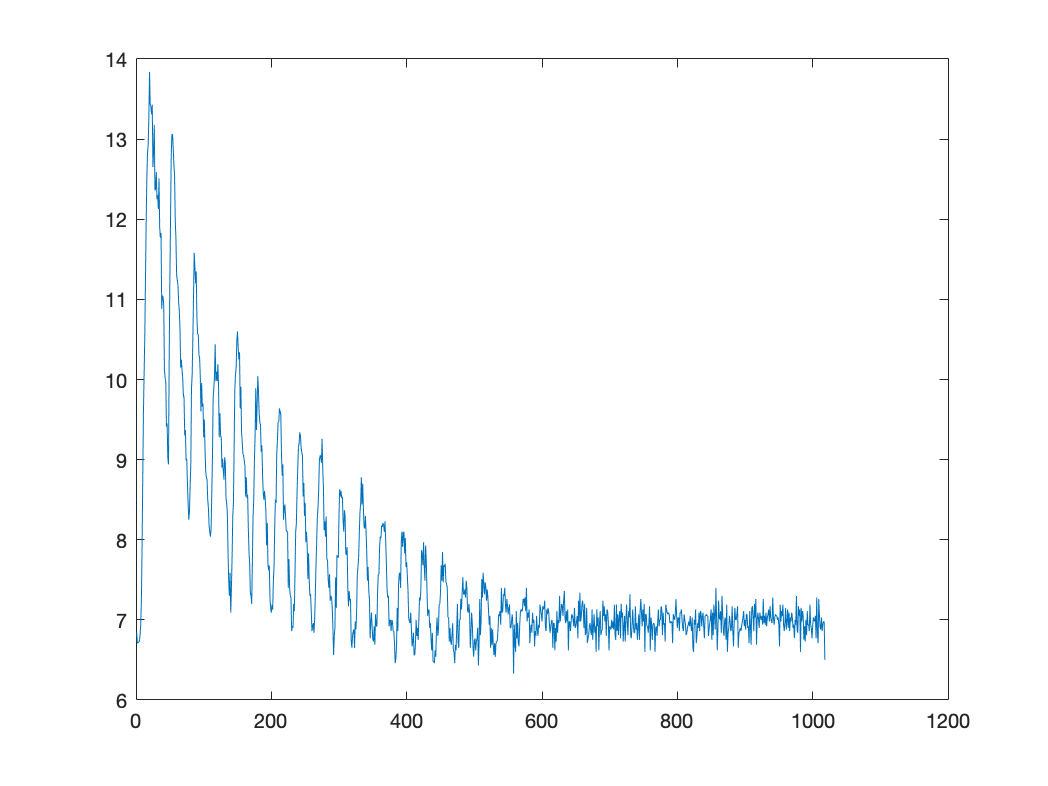

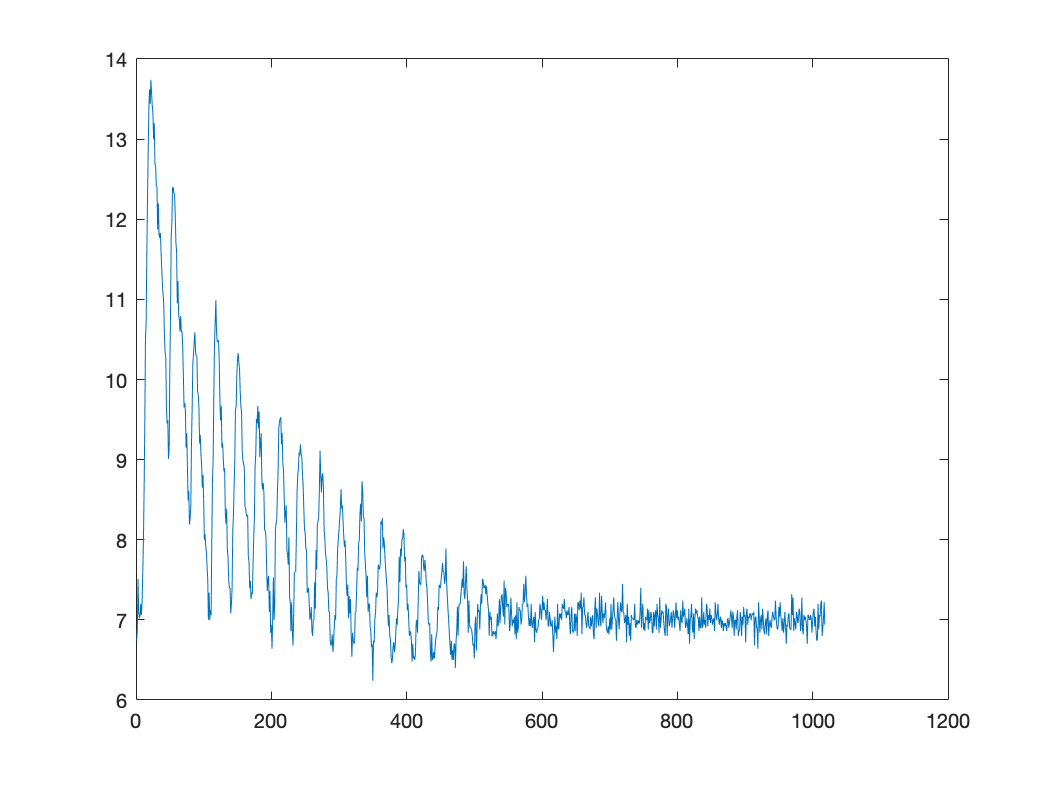

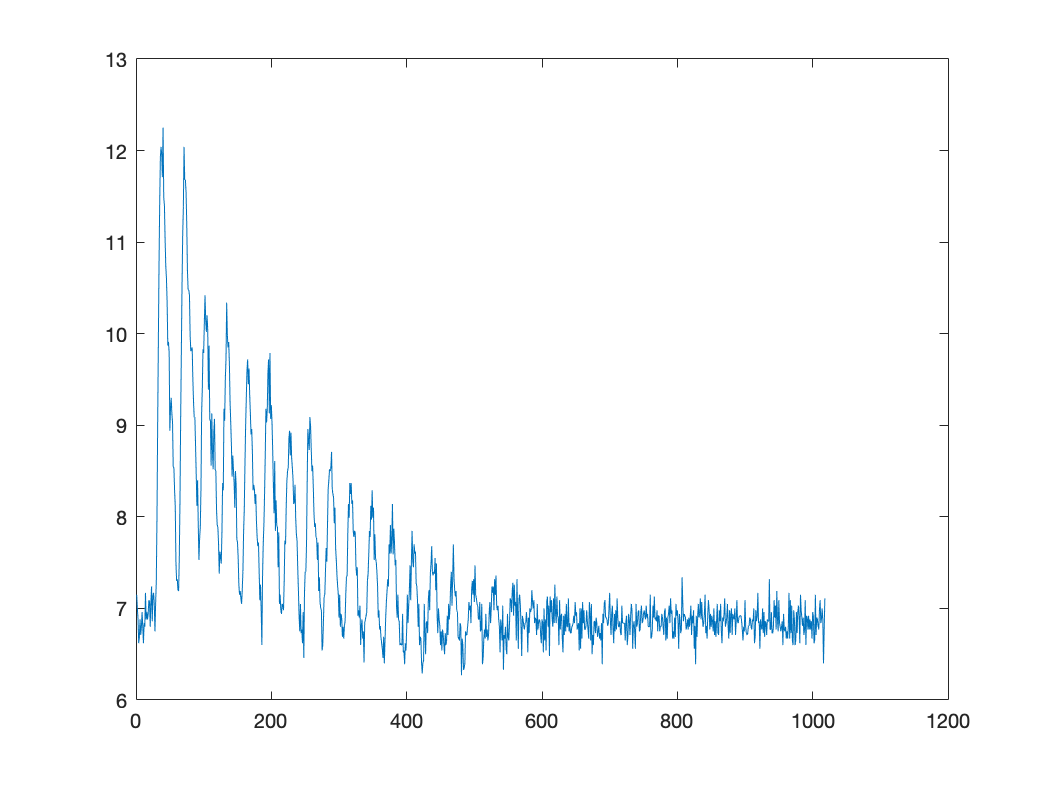

h1 = x(:,4);
h2 = x(:,8);
for j = 1:16
    plot (h1((1018*(j-1))+1:1018*j));
    figure;
    plot (h2((1018*(j-1))+1:1018*j));
    figure;
end

2+4

ans = 6

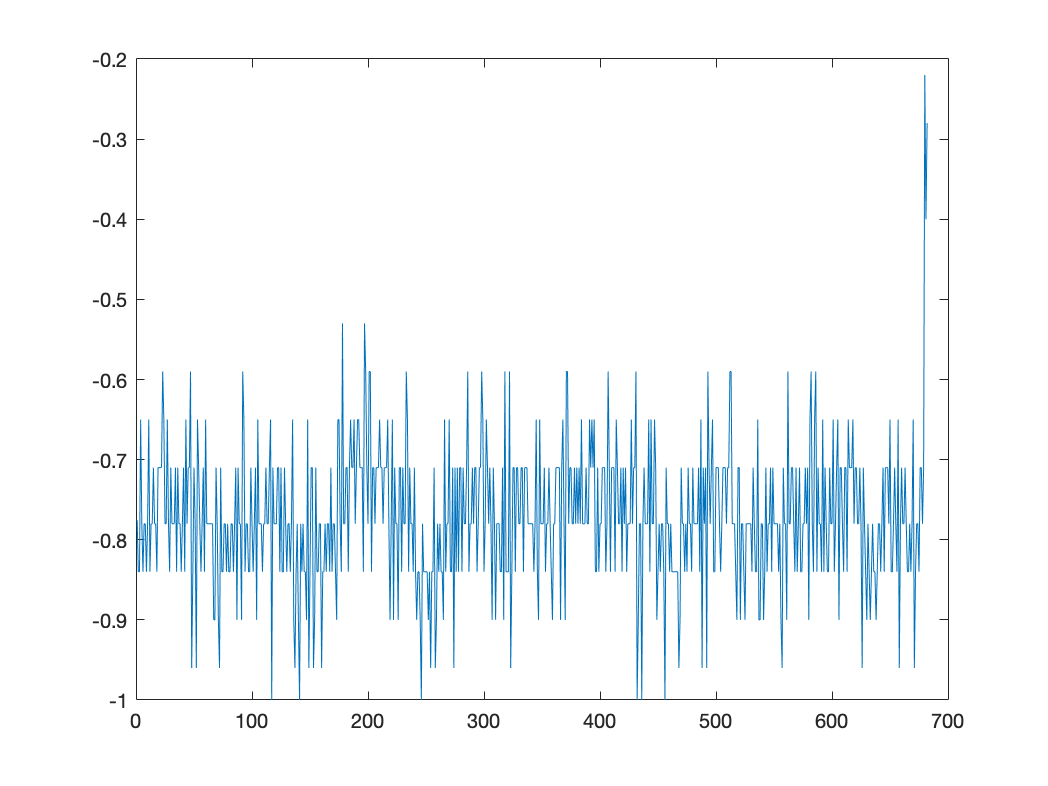

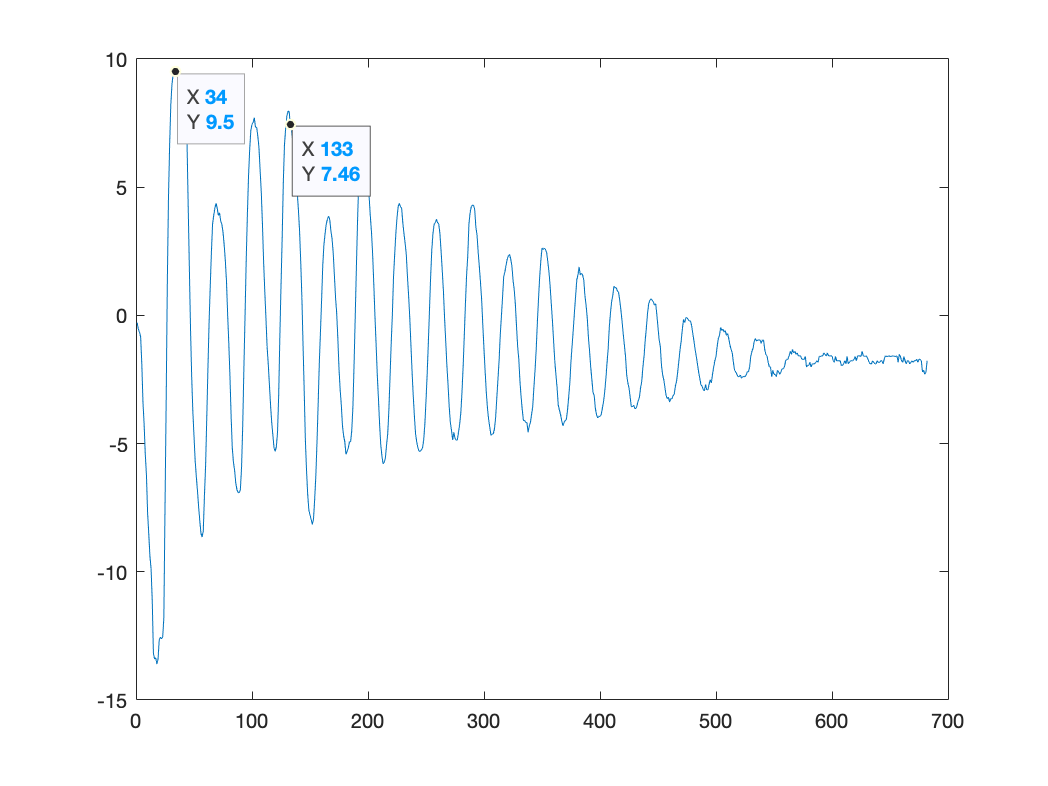

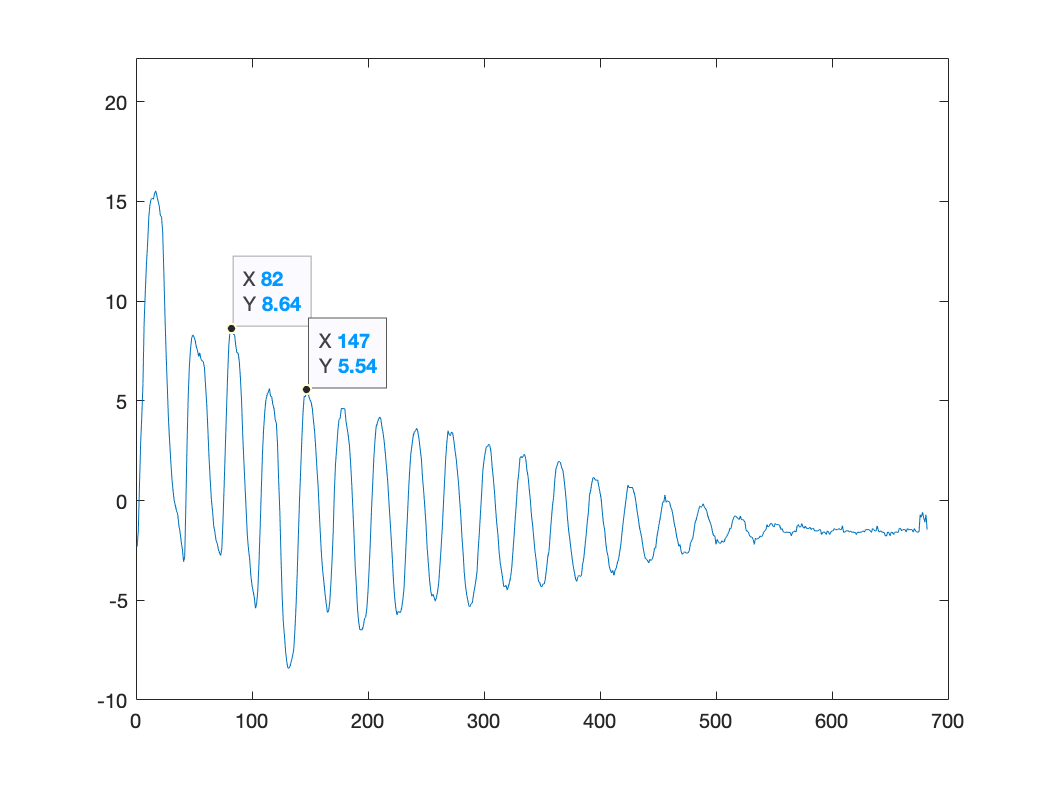

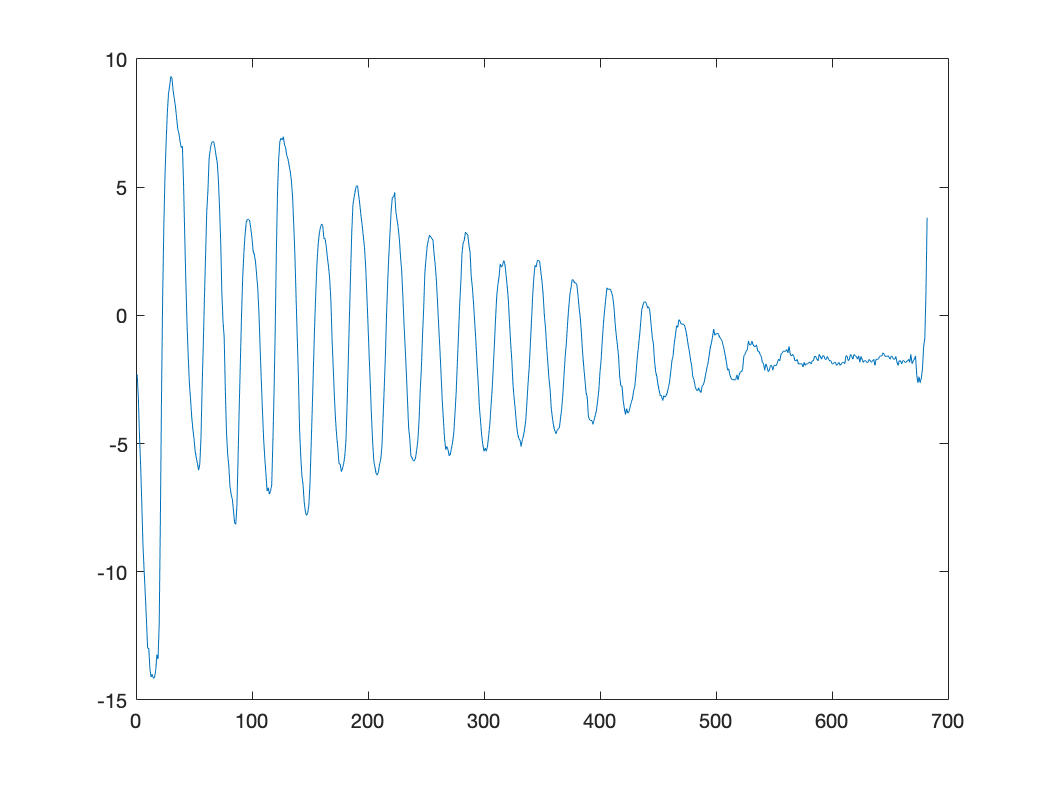

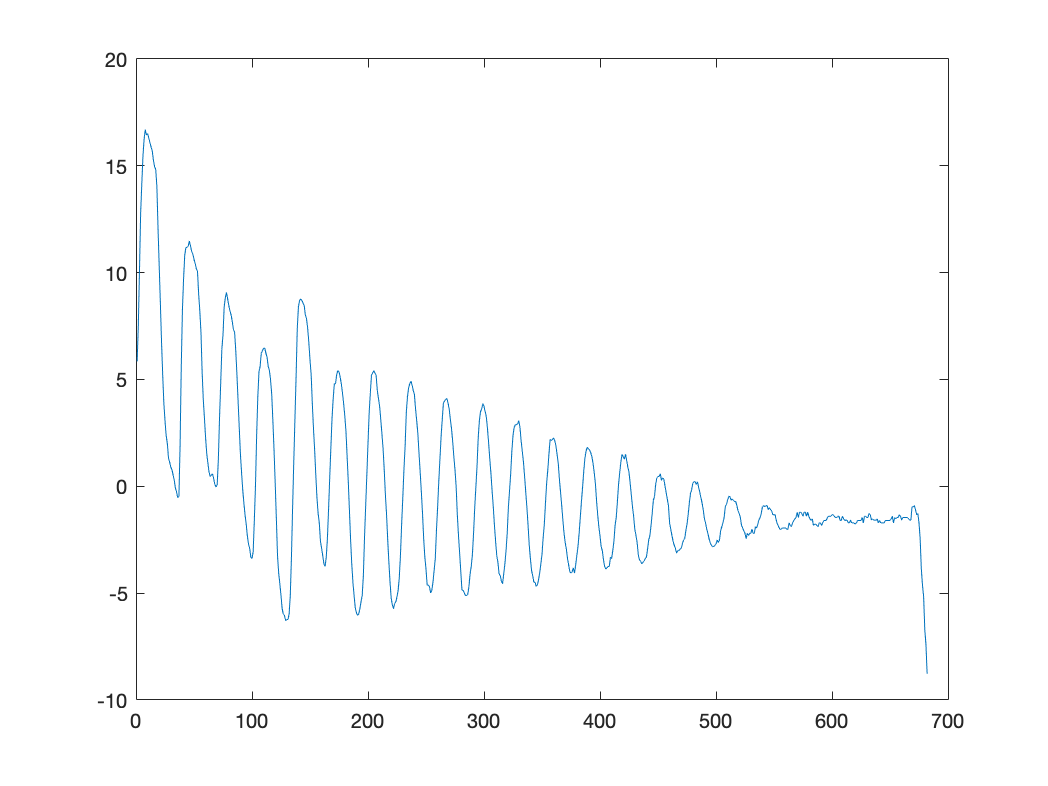

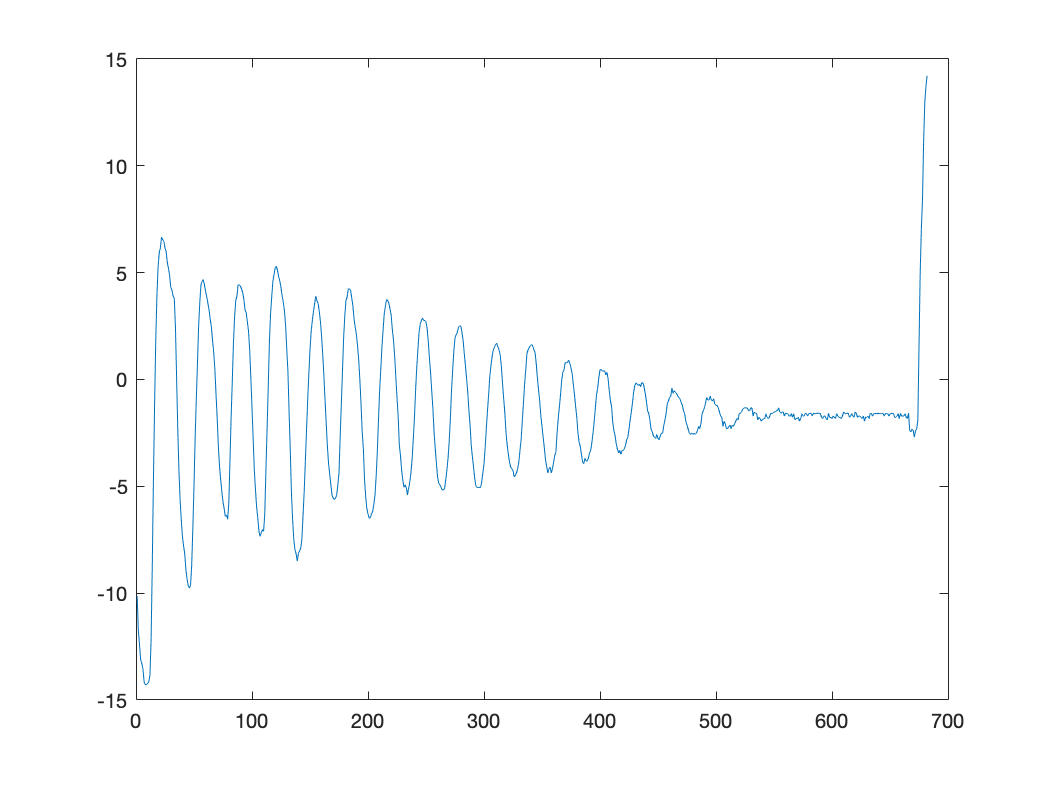

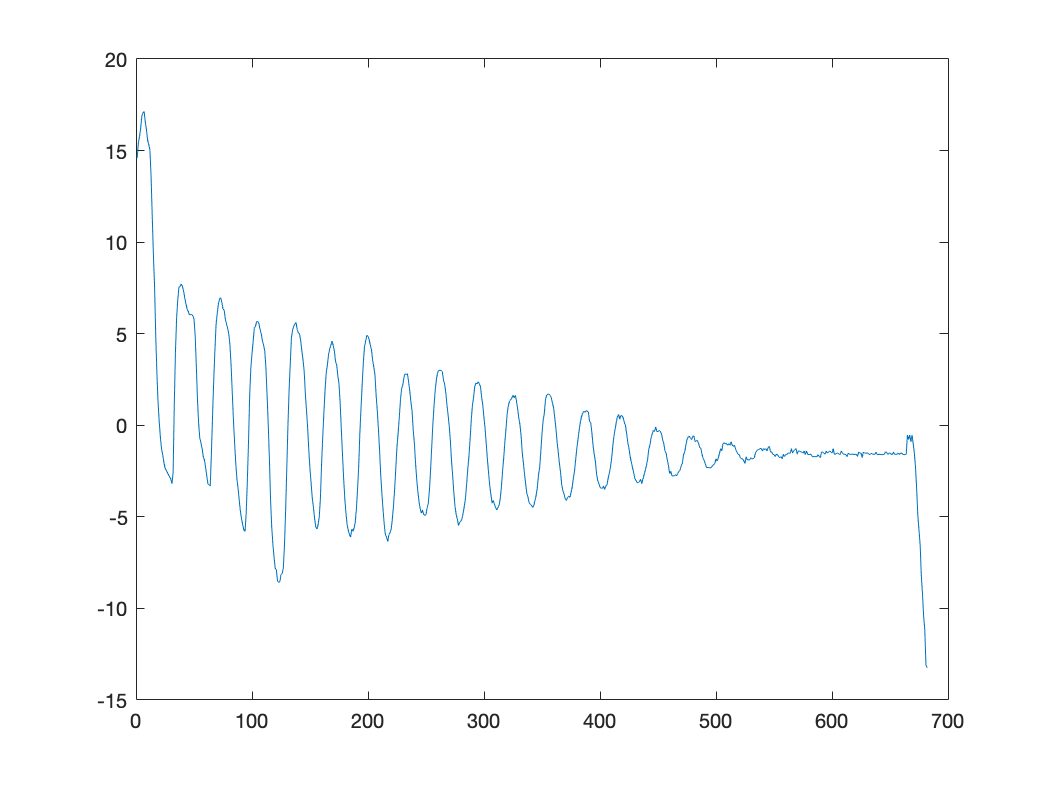

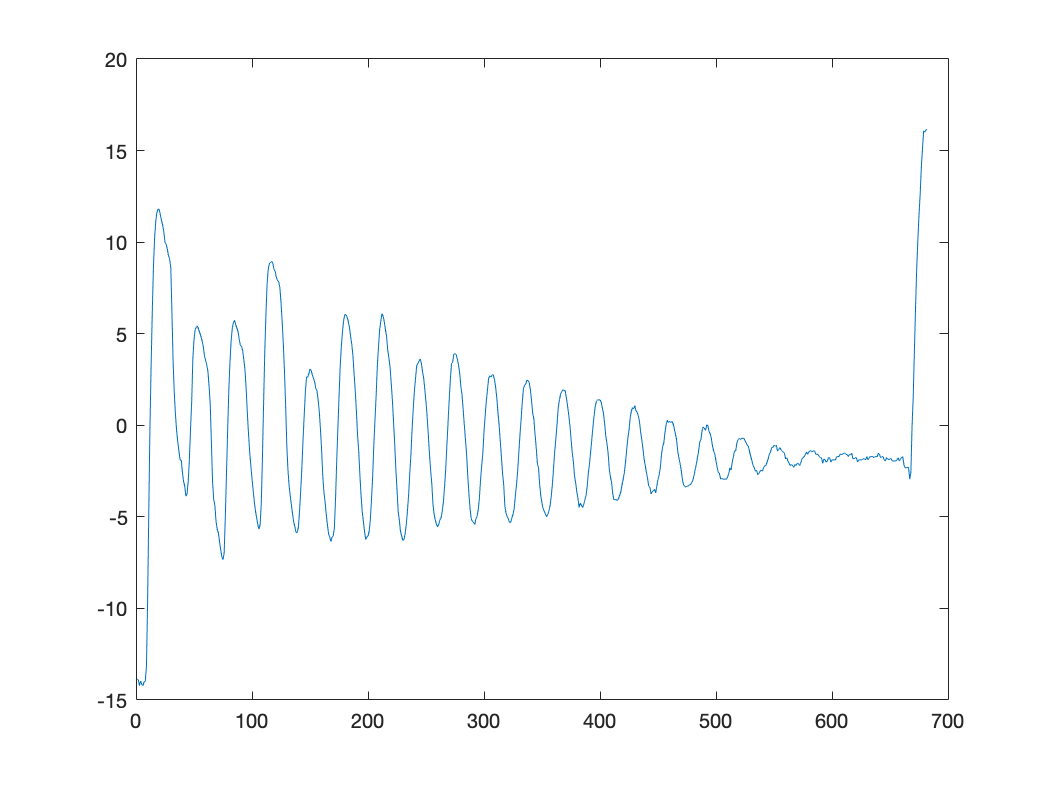

h12 = x(:,2);
for j = 1:33
    plot (h12((682*(j-1))+1:682*j));
    figure;
end